# Vibrating String

## 1D Wave Equation

A vibrating string can be represented by the 1D wave equation. The 1D wave equations is


$$\frac{\partial^2 u}{\partial t^2} = c^2 \frac{\partial^2 u}{\partial x^2}$$


where $u(x,t)$ is the displacement of the string and the wavespeed $c$ is


$$c = \frac{T}{\rho}$$


where $T$ is the string tension and $\rho$ is the density.

Assuming that the string is fixed at both ends, $x=0$ and $x=L$, the boundary conditions are 


$$u(0,t) = u(L,t) = 0$$


Also, assume that the string has been plucked so that  the string is initially displaced according to a function $u_0(x)$ but has zero initial velocity, in mathematical terms:

$u(x,0) = u_0$    and    $\left. \frac{\partial u}{\partial t} (x,0)= 0$

[image of the boundary condition/initial condition]

## Series Solution

**Separation of variables**

Assume that the solution is a product:


$$u(x,t) = X(x)T(t)$$


Under this assumtion, the PDE may be written as


$$X T'' = c^2 T X''$$


or


$$\frac{1}{c^2} \frac{T''}{T} =  \frac{X''}{X} = -\lambda$$


where $\lambda$ is an (unknown) constant. Therefore, the two equations can be separated as

$T'' = -\lambda c^2 T$    and    $X'' = - \lambda X$

**Solution for **$X$

Because the boundaries are fixed as $u(0,t) = u(L,t) = 0$, the equation for $X$ is a boundary value problem with $X(0) = X(L) = 0$. Assuming a solution of the form $X = e^{r x}$ implies the charactersitic equation 


$$r^2 =  - \lambda$$


with roots $r = \pm i \sqrt{\lambda}$. The purely complex roots imply solutions of the form


$$X(x) = c_1 \cos(\sqrt{\lambda} x) + c_2 \sin (\sqrt{\lambda} x)$$


The first boundary condition implies $X(0) = c_1 \cos( 0 ) + c_2 \sin (0) = 0$, or $a_1 = 0$. Therefore


$$X(x) = c_2 \sin(\sqrt{\lambda} x)$$


Applying the second condition, $X(L) = c_2 \sin( L \sqrt{\lambda} ) = 0$. Therefore


$$L\sqrt{\lambda} =  n \pi$$


for integer $n$. Solve for the eigenvalues to find that $\lambda = (n \pi / L)^2$ with the eigenfunctions


$$X(x) = \sin \left(\frac{n \pi}{L} x \right)$$


The coefficient $c_2$ is neglected as it will be accounted for in the series solution.

**Solution for **$T$

Using the eigenvalues found while solving for $X$, the ODE for $T$ is


$$T'' = - \frac{ n \pi }{c^2 L} T$$


Follow the same procedure as for $X$ and you will find solutions of the form 


$$T(t) = d_1 \cos\left( \frac{n \pi c}{L} t \right) + d_2 \sin \left(\frac{n \pi c}{L} t \right)$$


**Series solution**

Because $n$ is any integer and the PDE is linear, the superposition of product solutions also solves the PDE:


$$u(x,t) = \sum_{n=1}^\infty
 a_n \cos\left( \frac{n \pi c}{L} t \right) \sin \left(\frac{n \pi}{L} x \right) 
 + b_n \sin \left(\frac{n \pi c}{L} t \right) \sin \left(\frac{n \pi}{L} x \right)$$


Applying the first initial condition $u(x,0) = u_0$ implies


$$u_0 = \sum_{n=1}^\infty a_n \sin \left(\frac{n \pi}{L} x \right)$$


In this Fourier series, the coefficients $a_n$ can be evaluated as usual for a Fourier series:


$$a_n = \frac{2}{L} \int_{0}^{L} u_0(x) \sin \left( \frac{ n \pi }{L} x \right) dx$$


Applying the second initial condition $\left. \frac{\partial u}{\partial t} (x,0)= 0$ implies


$$\left. \frac{\partial u}{\partial t} (x,0)= \sum_{n=1}^\infty b_n \frac{n \pi c}{L} \sin \left(\frac{n \pi}{L} x \right) = 0$$


So $b_n = 0$. The final solution is therefore


$$u(x,t) = \sum_{n=1}^\infty
 a_n \cos\left( \frac{n \pi c}{L} t \right) \sin \left(\frac{n \pi}{L} x \right) $$


where the coefficients $a_n$ are determined by the initial displacement, $u_0$.

## Visualization

**Physical constants**

First, define the physical constants.

L = 1; % Domain length (m)
T = 100;
rho = 10;
c = sqrt(T/rho)

c = 3.1623

**Initial displacement**

Assume that the string is plucked at a point $x = p$ with a displacement of $u_p$ and can be approximated by the piecewise linear function illustrated below. Run this section. To show the initial condition

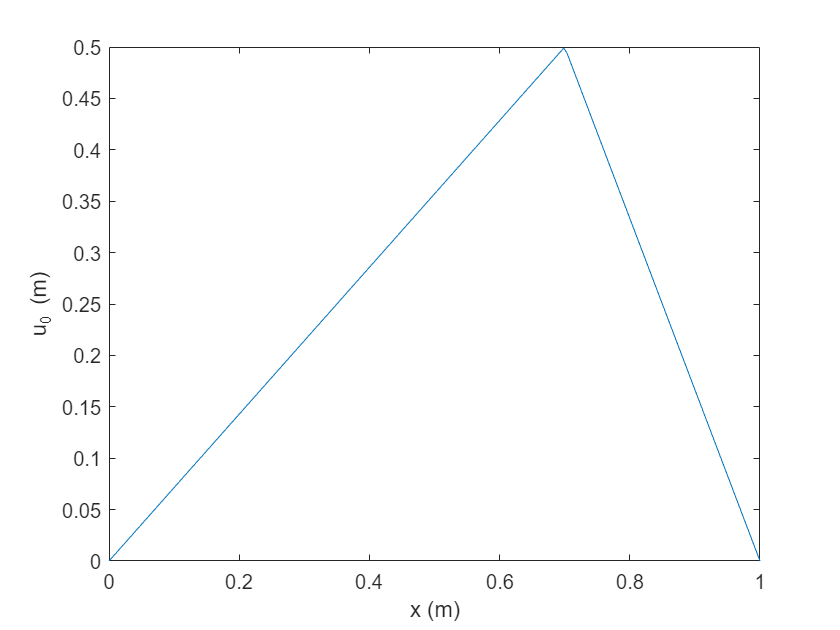

p = 0.7; % Pluck position (m)
up = 0.5; % Displacement at the plucked location (m)
Nx = 200; % Points to plot/estimate integrals

x = linspace(0,L,Nx);
u0 = interp1([0,p,L],[0,up,0],x);

plot(x,u0)
xlabel('x (m)')
ylabel('u_0 (m)')

**Fourier series estimation**

The coefficients $a_n$ can be evaluated analytically, but it is simpler to estimate them numerically. The coefficients are estimated here using the trapezoid rule.

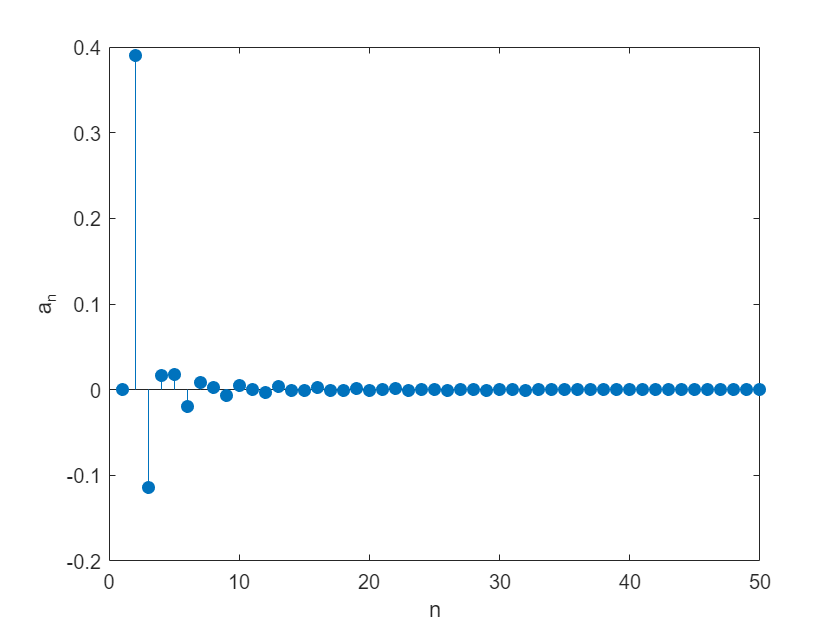

Nmodes = 50; % Number of Fourier modes used in the estimation

a = zeros(1,Nmodes);
for n = 0:(Nmodes-1)
    a(n+1) = 2/L*trapz(x,sin(n*pi/L*x).*u0);
end

stem(a,"filled")
xlabel("n")
ylabel("a_n")

Initial condition fourier series representation

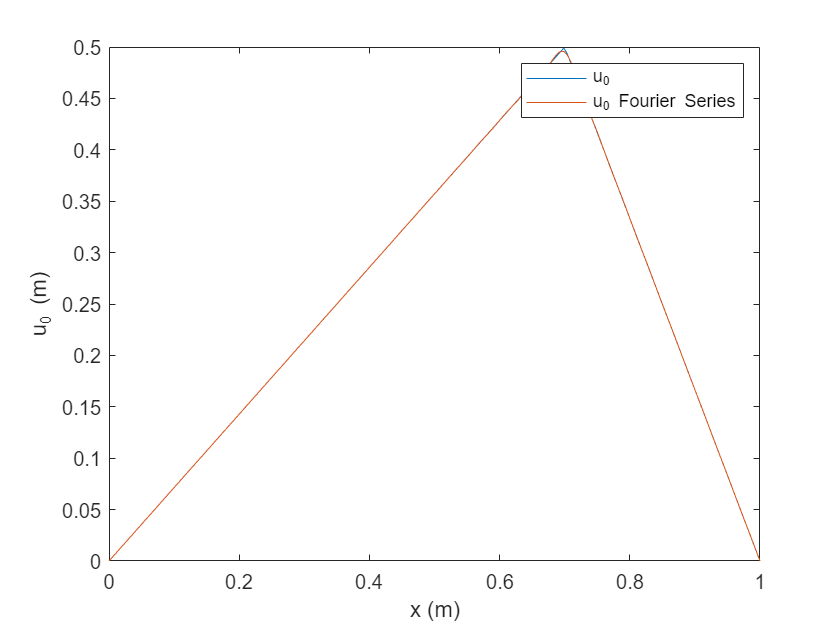

u0s = x*0;
for n = 0:(Nmodes-1)
    u0s = u0s + a(n+1)*sin(n*pi/L*x);
end
plot(x,u0,x,u0s)
xlabel('x (m)')
ylabel('u_0 (m)')
legend("u_0","u_0 Fourier Series")

**Solution animation**

The solution to the PDE under the identified conditions is


$$u(x,t) = \sum_{n=1}^\infty
 a_n \cos\left( \frac{n \pi c}{L} t \right) \sin \left(\frac{n \pi}{L} x \right) $$


The solutions is visualized by looping through the time variable and computing the solution at each time.

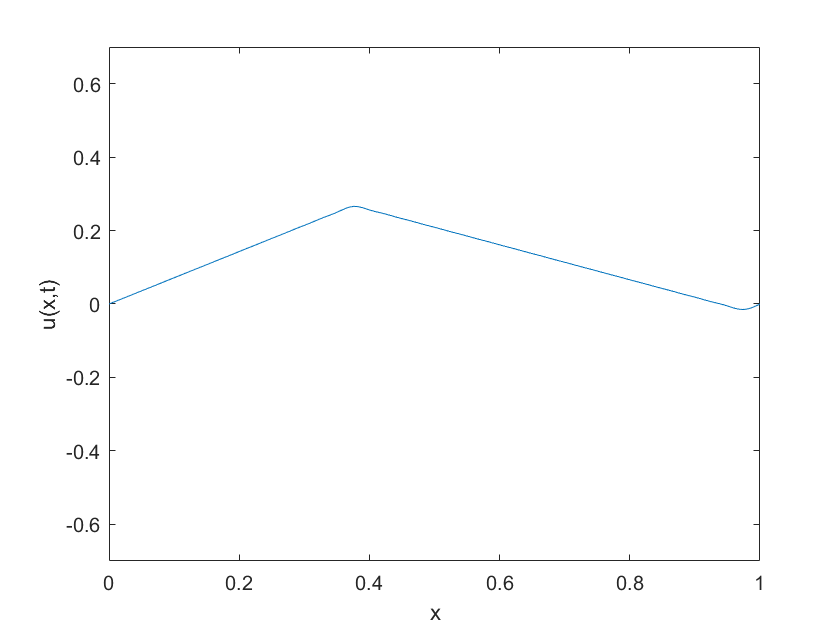

Nt = 200;
tf = 2;
t = linspace(0,tf,Nt);
U = [];

figure
ax = axes;
pHandle = plot(x,u0);
axis([0,L,-p,p])

ylabel('u(x,t)')
xlabel('x')
for nt = 1:Nt
    u = x*0;
    for n = 0:(Nmodes-1)
        u = u + a(n+1)*cos(n*pi*c/L*t(nt))*sin(n*pi/L*x);
    end
    U(nt,:) = u;
    pHandle.YData = u;
    drawnow
end